# Analiza harmoniczna sygnałów

Zastosowanie analizy harmonicznej sygnałów jest szeroko stosowane, w większości miejsc, gdzie spotykamy się z przetwarzaniem sygnałów. Możliwość operowania na dziedzinie częstotliwości sygnału, zamiast poleganiu tylko na dziedzinie czasu pozwala wykrywać charakterystyczne składowe sygnału.  Pozwala to na lepsze zrozumienie fizyczne sygnału. 

Analiza harmoniczna ma również zastosowanie w codziennym życiu, spotyka się ją np. we wszelkich czynnościach dotyczących kompresji sygnałów czy obrazów. Polega to na pozbyciu się informacji o tych współczynnikach w widme sygwykorzystywane w aplikacjach takich jak asystenci głosowi i kamery monitorujące.

Telekomunikacjanału, które mają najmniejszy wpływ na dane. Oprócz tego z analizą sygnałów spotykamy się w rozpoznawaniu mowy i obrazów, np. korzystając z asystenta Google, czy na badaniu EEG, aby lepiej zrozumieć procesy, które odbywają się w umyśle ludzkim. 

## Zad przygotowawcze 1

a) Pierwszy warunek nie jest spełniony np. przez funkcę: $tan(t)$.

b)Drugi warunek nie jest spełniony, przez funkcję $sin(\frac{1}{t})$, która w otoczenie punktu $t=0$ przyjmuje nieskończoną liczbę ekstremów w jednym okresie.

c) Trzeciego warunku Dirichleta dotyczącego skończonej liczby nieciągłości nie spełnia np. Funkcja Dirichleta:


$$x(t) =  \begin{cases}  1 & \text{dla } t \in \mathbb{Q} \\ 0 & \text{dla } t \notin \mathbb{Q} \end{cases}$$


## Zad przygotowawcze 2

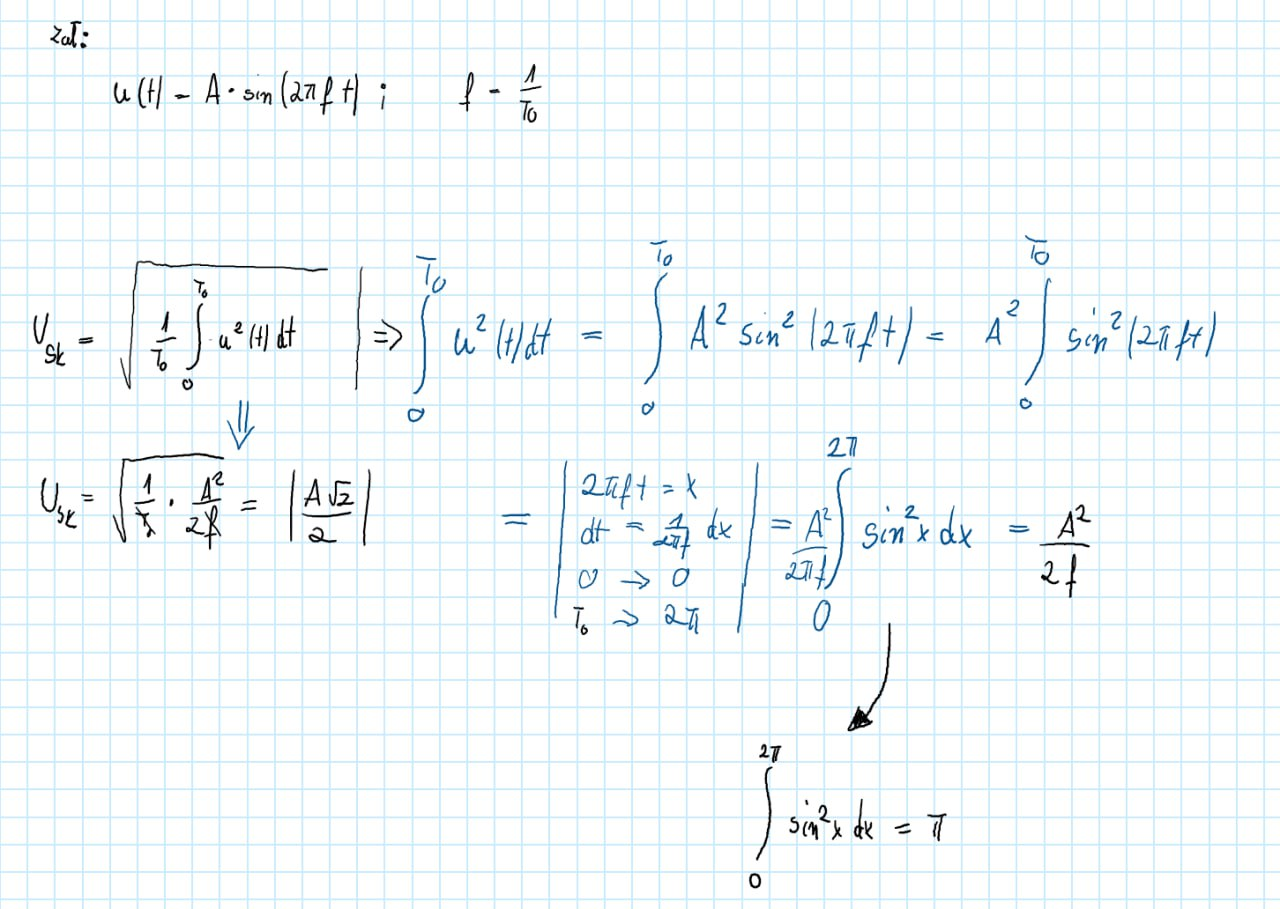

clear, clc

## Ćwiczenie + Zadanie 1

Użycie bibliotek służących do obliczeń symbolicznych w środowisku Malab, w celu przedstawienia pulsu trójkątnego w dziedzinie częstotliwości. Na początku stworzono funkcję definiującą puls trójkątny

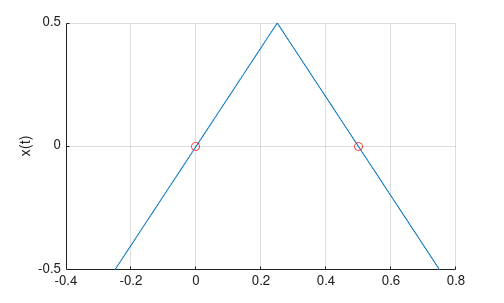

clear all; close all;

syms t t1 t2 offset x 

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice całkowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;

figure;
hold on
fplot(x,BND); 
grid on; 
ylabel('x(t)')
plot([0,0.5],[0, 0], 'ro')
hold off

W dalszej części ćwiczenia obliczono parametry charakteryzujące dany przebieg, takie jak wartość średnia i skuteczna.

**Określenie podstawowych parametrów:**

Wartość średnia

avarage_value = int(x,BND)/(t2-t1)

$$avarage\_value = 0$$

signal_energy = int(x^2,BND)

$$signal\_energy = \frac{1}{12}$$

avarage_power = signal_energy/(t2-t1)

$$avarage\_power = \frac{1}{12}$$

normal_power = sqrt(avarage_power)

$$normal\_power = \frac{\sqrt{3}}{6}$$

## Zadanie + Ćwiczenie 2

Na podstawie danych z Ćwiczenia 1, obliczono współczynniki dla przedstwienia sygnału w postaci szeregów Fourier'a, korzystając ze wzoru na zespolonych współczynników dla postaci wykładniczej. Wyniki przedstawiono na poniższym schemacie.

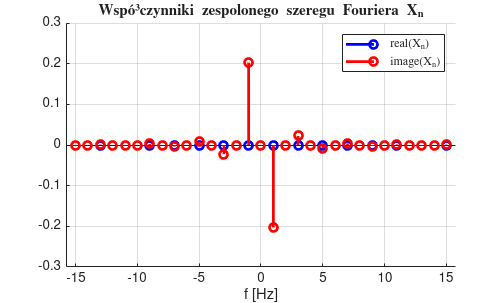

NT = 15;
X=[];
ind = -NT : NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end
									
figure; hold on; 
stem(ind*f0,real(X),'b','LineWidth',2); 
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2); 
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Wspó³czynniki zespolonego szeregu Fouriera X_n')

## Zadanie 3

W zadaniu 3 przedstawiono na wykresie współczynniki dla postaci trygonometrycznej. Współczynniki te obliczono korzystając z wzorów przedstawionych w skrypcie.

n = 0:15;
a = arrayfun(@(n) 1/(t2-t1) * int(x*cos(w0*n*t), BND),n)

$$a = \left(\begin{array}{cccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

b = arrayfun(@(n) 1/(t2-t1) * int(x*sin(w0*n*t), BND),n)

$$b = \left(\begin{array}{cccccccccccccccc} 0 & \frac{2}{\pi^{2}} & 0 & -\frac{2}{9\,\pi^{2}} & 0 & \frac{2}{25\,\pi^{2}} & 0 & -\frac{2}{49\,\pi^{2}} & 0 & \frac{2}{81\,\pi^{2}} & 0 & -\frac{2}{121\,\pi^{2}} & 0 & \frac{2}{169\,\pi^{2}} & 0 & -\frac{2}{225\,\pi^{2}} \end{array}\right)$$

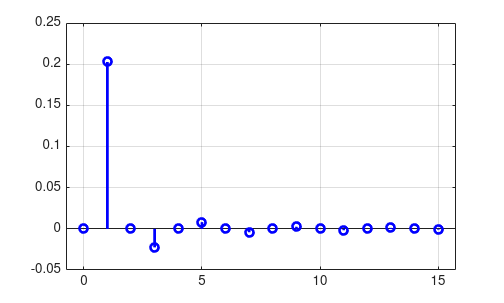

clf
stem(n*f0,b,'b','LineWidth',2); 
grid on

## Zadanie 4

Na podstawie współczynników obliczonych we wcześniejszych zadaniach wykonano rekonstrukcje sygnału, korzystając z faktu przedstawienia sygnału w rozwinięciu w szereg Fourier'a:

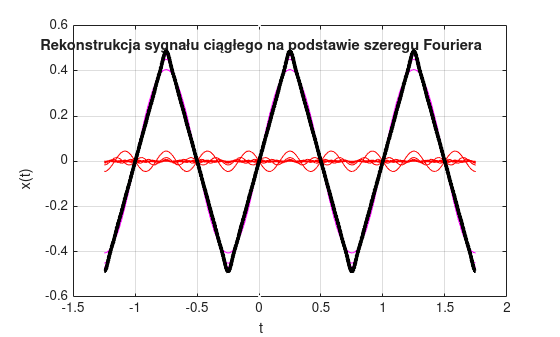

step = (BND(2) - BND(1))/1000;	
tt = [BND(1)-T0 : step: BND(2) + T0];
xx = zeros(1,length(tt));
xx =  xx + a(1); % skladowa stala
				
figure
plot(tt,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)'); 
pause(0.5)
				
for n = 1 : NT
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r'); plot(tt,xx,'m');
    title(sprintf('n = %d',n+1)); pause(0.5)
end

plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygnału ciągłego na podstawie szeregu Fouriera')

## Zadanie domowe

Zadanie dotyczące pisania skryptu wykonano poniżej natomiast część dotyczącą obliczeń wykonanych ręcznie umieszczono na końcu pliku PDF.

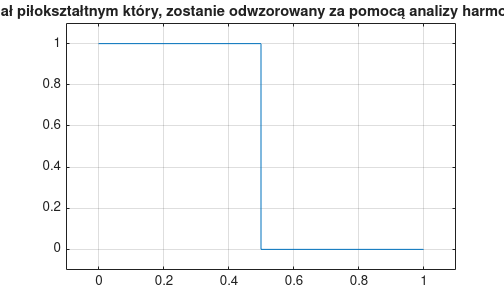

dt = 10^-5;
f = 1;
T0 = 1/f;
w0 = 2*pi*f;
t = 0:dt:T0;


y = rectpuls(t);
% Alternatywnie wszystkie obliczenia można przeprowadzić dla sygnału
% piłokształtnego generowanego w linijce poniżej:
% y = sawtooth(2*pi*f*t);

figure
plot(t,y)
title("Sygnał piłokształtnym który, zostanie odwzorowany za pomocą analizy harmonicznej")
axis([-0.1 1.1 -0.1 1.1])
grid on

Ilość wyliczanych współczynników:

N = 50;
n = 0:N;

Obliczenie wektorów współczynników w postaci trygonometrycznej

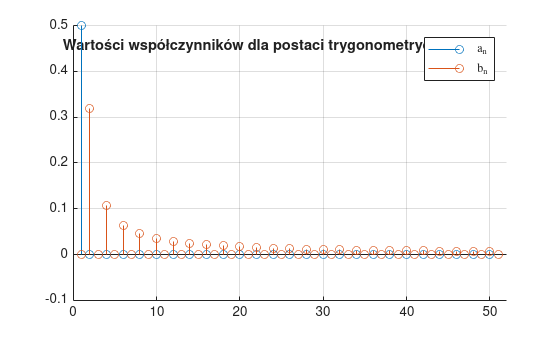

a = arrayfun(@(x) 1/T0 * sum(y.*cos(w0*x*t))*dt, n);
b = arrayfun(@(x) 1/T0 * sum(y.*sin(w0*x*t))*dt, n);

clf
figure
hold on
stem(a)
stem(b)
legend('a_n', 'b_n')
title("Wartości współczynników dla postaci trygonometrycznej")
grid on
hold off

Tworzenie odwzorowania sygnału

num_okres = 5

num_okres = 5

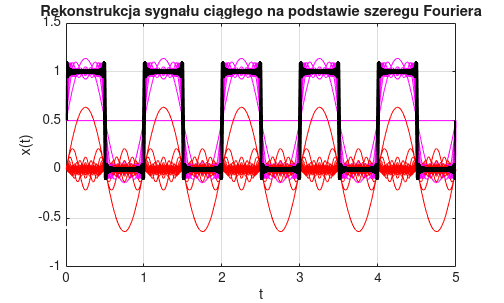

tt = 0:dt:num_okres*T0;
xx = zeros(1,length(tt));
xx =  xx + a(1); % skladowa stala
				
figure
plot(tt,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)'); 
pause(0.5)
				
for n = 1 : N
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r'); plot(tt,xx,'m');
    title(sprintf('n = %d',n+1)); 
    pause(0.01)
end
plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygnału ciągłego na podstawie szeregu Fouriera')

# Wnioski

Podczas laboratorium zapoznano się z matematycznym wstępem do teorii analizy harmonicznej sygnałów. Wszystkie obliczenia, które zostały przedstawione w instrukcji znalazły swoje przełożenie w trakcie tworzenia skryptu w Matlabie. Atrakcyjność tych zajęć polega na ciekawym sposobie połączenia dwóch części teorii, która w nadmiernej ilości mogłaby przytłoczyć oraz praktyki, ktora sama w sobie nie wniosłaby nic ze zrozumienia jak używane powszechnie funkcje działają. Sam temat jest bardzo ciekawy i mam nadzieję poszerzać wiedzę na jego temat w najbliższej przyszłości.